## **EEGLAB OpenNeuro to DL pipeline**

In this example, we present the pipeline that downloads the [EEG dataset](https://openneuro.org/datasets/ds003061/versions/1.1.2) from [OpenNeuro](https://docs.openneuro.org/user_guide.html) archive [1], pre-processes it using [EEGLAB](https://sccn.ucsd.edu/eeglab/index.php) toolbox [2] and formats as input for deep learning-based classification. The data was collected at the Meditation Research Institute (MRI) in Rishikesh, India under the supervision of Arnaud Delorme, PhD ([Swartz Center for Computational Neuroscience](https://sccn.ucsd.edu/)). The data is stored in a [BIDS](https://bids.neuroimaging.io/) format [3], a standard defining the organization of neuroimaging/accompanying behavioral data, as well as the relevant metadata, facilitating the data sharing and reproducibility.

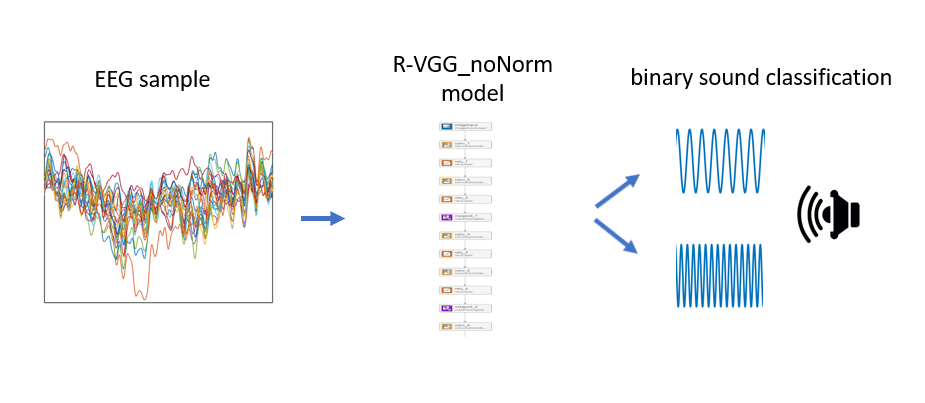

**Background on Dataset**

The dataset consists of a scalp EEG recordings from 13 participants, each providing 3 13-min sessions. Participants were asked to keep the eyes closed during recording, while being presented with 750 **auditory stimuli**, divided in 3 groups: **standard **(500 Hz pure tone lasting 60 ms), **oddball** (1000 Hz pure tone lasting 60 ms) and **distractors** (1000 Hz white noise lasting 60 ms). Sounds were presented at 1/sec rate. Participants were instructed to respond to oddball tone using a key press. 

Recording was performed using the standard [**10-20 EEG system**](https://en.wikipedia.org/wiki/10%E2%80%9320_system_(EEG)) (Active Two Biosemi system, Biosemi Inc.), with 1024 Hz sampling rate. The data in OpenNeuro dataset was subsequently resampled at 256 Hz. Individual samples consist of 1 sec signal across 144 channels, spanning the time window between the two consecutive tone onsets.

%explain the EEGLAB processing, interpolation etc. I guess interpolation is done to augment the data for DL. 

%maybe use AWS CLI for download

%describe open neuro, bids, eeglab
% *Run 'eeglab' from the folder containing the eeglab codes. This will add all 
% the relevant EEGLAB functions and directories to path.*
addpath('C:\Users\ivans\Downloads\eeglab_current\eeglab2023.1'); %check if eeglab is already installed, if not, download and install
%if not installed, add the directory selection for where to install eeglab
eeglab
eeglabPath = fileparts(which('eeglab'))

if 0
    % Load tutorial dataset
    [STUDY, ALLEEG] = pop_importbids('C:\Users\ivans\Downloads\ds003061\ds003061', 'eventtype', 'value', 'outputdir', 'C:\Users\ivans\Downloads\ds003061/ds003061-bidsdl');

## BIDS_DL plugin export

pop_studydl exports EEGLAB study into ML/DL data format

    pop_studydl(STUDY, ALLEEG, 'outputdir', fullfile(eeglabPath, 'ML_EXPORT'))
end

## Training with 12x12 interpolated data

The original 10-20 EEG montage contains 21 channels. One of the steps in pre-processing is interpolation, a mathematical operation that created artificial channels by combining the values of neighbouring channels. The purpose of this step is the data augmentation, a step whereby more training samples are created based on the existing samples, in order to improve the model performance. In addition, in the context of EEG data, the interpolation makes sense based on the brain signal mixing. The result of interpolation in our example is that pre-processed data consist of 144 channels (12x12).

Below we plot the average event-related potentials (ERPs) across all the channels and all the trials of a given tone.

## Create the datastore

imds = imageDatastore(fullfile(eeglabPath, 'ML_EXPORT', 'mat_files'), 'FileExtensions','.mat','IncludeSubfolders',true);

## Custom reader function

load_sample = @(x) x.Z_12; 
readfun = @(x) load_sample(load(x));
imds.ReadFcn = readfun;

## Preview the first sample of the datastore

sample = preview(imds);
fprintf('Sample size = %d, %d, %d\n', size(sample));

## Assigning the labels

%maybe the mismatch of labels and files happened at this sorting step
label_info = readtable(fullfile(eeglabPath, 'ML_EXPORT', 'labels_local.csv'));
label_info_sorted = sortrows(label_info,1);
label_col = label_info_sorted.Var7; % type of stimulus

row_selected = zeros(1,length(label_col), 'logical');

selected = { 'standard' 'oddball_with_reponse' };



for iSelected = 1:length(selected)
    %inds = strmatch(selected{iSelected}, label_col, 'exact');
    inds = strmatch(selected{iSelected}, label_col, 'exact');
    row_selected(inds) = true;
end
imds.Files = imds.Files(row_selected);
imds.Labels = categorical(label_col(row_selected));


## Checking the sample-label correspondence

As the EEG samples and sample labels are combined from different files, check_correspondence function verifies the correct sample-label correspondence.

check_correspondence(label_info_sorted, imds, row_selected)

If a single sample-label pair with the same index don't correspond, the error message is displayed.

## Compute class weights if classes are imbalanced

In real life data, classes are often **imbalanced**. The class imbalance is defined as the skewed proportions of individual class samples, which could affect the model training and bias the inference is biased towards the **majority class** (the class with largest proportion of samples). Here is a more detailed [explanation](https://medium.com/nerd-for-tech/class-imbalance-problem-and-ways-to-handle-it-4861a195398a) on the influence of class imbalance on training performance. One of the possible options to deal with the class imbalance is assigning the **class weights, **which set the relative importance of individual classes in training. Class weights are defined as the inverse frequencies of individual classes, so the over-represented class(es) are assigned the weights inversely proportional to their frequencies. 

classes = unique(imds.Labels);
uniqueLab = cellstr(unique(imds.Labels));
allLabels = cellstr(imds.Labels);
for iCat = 1:length(uniqueLab)
    n(iCat) = sum(cellfun(@(x)isequal(uniqueLab{iCat}, x), allLabels));
end
classWeights = n/sum(n);

% split datastore into training, testing and validation
rng(1)
[train_imds, val_imds, test_imds] = splitEachLabel(imds, 0.6, 0.3, 0.1, 'randomized');


Note: the labels here have been sorted to match the order of Files (works for Mac/Linux and AWS - need to check for Windows).

## Constructing & Training Network

Here we construct a modified VGG model, which is a simple to understand yet powerfull deep learning model [4]. This model represents a convolutional neural network with 27 layers, with the input layer (`imageInputLayer`) corresponding to the individual sample dimensions (12 x 12 x 256 in this case) and the output layer (`classificationLayer`) reflecting the number of class labels (1 x 2). A detailed explanation of the concept of convolutional neural networks and an overview of individual components (layers, activation functions etc.) may be found [here](https://en.wikipedia.org/wiki/Convolutional_neural_network).

MATLAB `classificationLayer` function, which constructs the classification output layer of a given neural network, provides the optional parameter ClassWeights to account for class weights in training process. 

channels = [12, 12]; %range of channels 
num_samples = 2048; %num of samples
image_size = [channels(1) channels(2) 256]; 
num_labels = size(unique(train_imds.Labels),1);

layers = [
    imageInputLayer(image_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer('Name','classoutput','Classes', classes, 'ClassWeights', classWeights)]; % The 'ClassWeights' option allows the class importance assignment inversely proportional to class frequency.


Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'ValidationData', val_imds, ... the datastore containing validation labels
    'Plots','training-progress',...% allows the real-time monitoring of training progress
    'MaxEpochs',10, ...% the n of training epochs. All the samples are presented once during a single epoch.
    'MiniBatchSize',40);


Train the network

eeg_net = trainNetwork(train_imds,layers,options);
[YPred,err] = classify(eeg_net, train_imds); performance1 = sum(0+ (train_imds.Labels == YPred))/length(YPred);
[YPred,err] = classify(eeg_net, val_imds  ); performance2 = sum(0+ (  val_imds.Labels == YPred))/length(YPred);
[YPred,err] = classify(eeg_net, test_imds ); performance3 = sum(0+ ( test_imds.Labels == YPred))/length(YPred);
fprintf('Percent correct training   is %1.2f %%\n', performance1*100);
fprintf('Percent correct validation is %1.2f %%\n', performance2*100);
fprintf('Percent correct testing    is %1.2f %%\n', performance3*100);

### **References**

[1] Gorgolewski, K., Esteban, O., Schaefer, G., Wandell, B. and Poldrack, R., 2017. OpenNeuro—a free online platform for sharing and analysis of neuroimaging data. *Organization for human brain mapping. Vancouver, Canada*, *1677*(2).

[2] Delorme, A. and Makeig, S., 2004. EEGLAB: an open source toolbox for analysis of single-trial EEG dynamics including independent component analysis. *Journal of neuroscience methods*, *134*(1), pp.9-21.

[3] Pernet, C.R., Appelhoff, S., Gorgolewski, K.J., Flandin, G., Phillips, C., Delorme, A. and Oostenveld, R., 2019. EEG-BIDS, an extension to the brain imaging data structure for electroencephalography. *Scientific data*, *6*(1), p.103.

### **Helper Functions**

function check_correspondence(label_info_sorted, imds, row_selected)

selected_files = label_info_sorted.Var1(row_selected);
imds_files     = imds.Files;

for iFile = 1:length(selected_files)
    if isempty(strfind(imds_files{iFile}, selected_files{iFile}(3:end)))
        error('Mismatch at position %d, label %s and folder %s', iFile, imds.Files{1}, selected_files{iFile}(3:end));
    end
end
end

